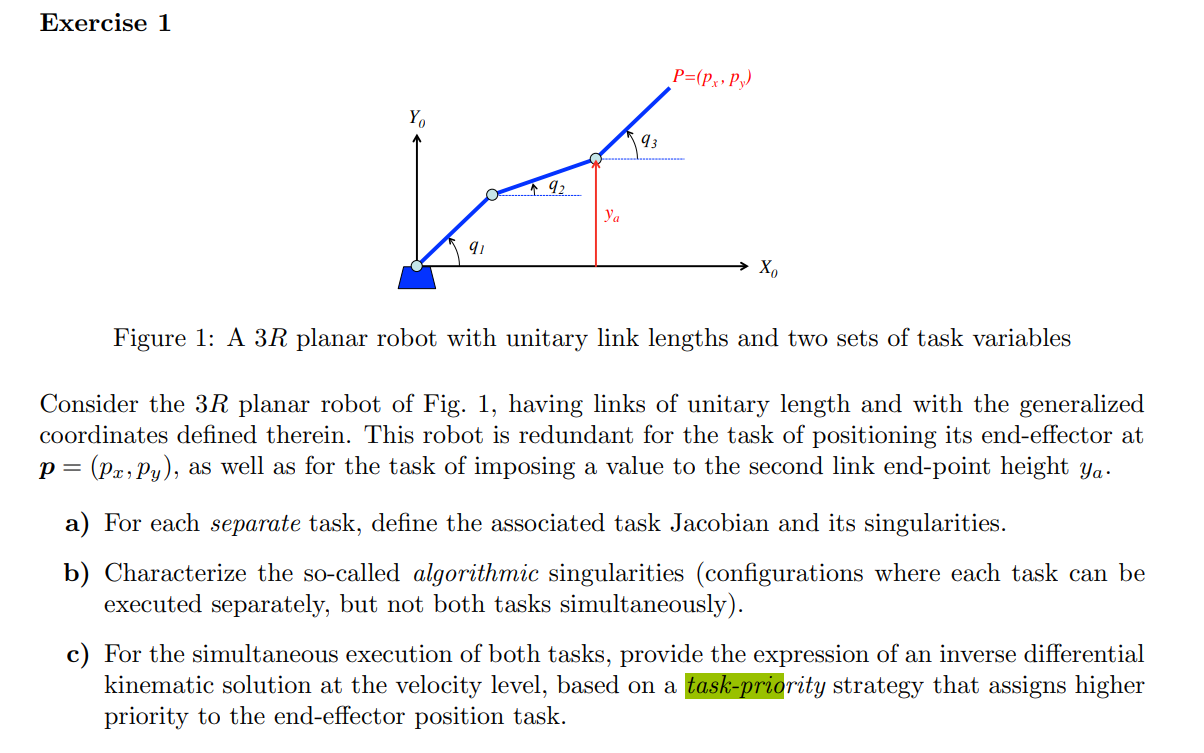

clc 
clear all
close all
syms q_1 q_2 q_3 q_dot_1 q_dot_2 q_dot_3 real

% addpath("Functions/Robotics1") % Linux
% addpath("Functions/Robotics2") % Linux
addpath("Functions\Robotics1") % Windows
addpath("Functions\Robotics2") % Windows

q = [q_1 q_2 q_3]';
q_dot = [q_dot_1 q_dot_2 q_dot_3]';

% unitary lenght so l = 1
f_a = [cos(q_1) + cos(q_2) + cos(q_3);
       sin(q_1) + sin(q_2) + sin(q_3)]

$$f\_a = \left(\begin{array}{c} \cos\left(q_{1}\right)+\cos\left(q_{2}\right)+\cos\left(q_{3}\right)\\ \sin\left(q_{1}\right)+\sin\left(q_{2}\right)+\sin\left(q_{3}\right) \end{array}\right)$$

f_b = sin(q_1) + sin(q_2)

$$f\_b = \sin\left(q_{1}\right)+\sin\left(q_{2}\right)$$


% tasks jacobian
J_a = simplify(jacobian(f_a, q'))

$$J\_a = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right) \end{array}\right)$$

J_b = simplify(jacobian(f_b, q'))

$$J\_b = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & 0 \end{array}\right)$$


% tasks singularities
det_J_a1 = simplify(det(J_a(:, 1:2)))

$$det\_J\_a1 = -\sin\left(q_{1}-q_{2}\right)$$

det_J_a2 = simplify(det([J_a(:, 1) J_a(:, 3)]))

$$det\_J\_a2 = -\sin\left(q_{1}-q_{3}\right)$$

det_J_a3 = simplify(det(J_a(:, 2:3)))

$$det\_J\_a3 = -\sin\left(q_{2}-q_{3}\right)$$

% task a q1 = q2 = q3
rank_J_a = rank(J_a)

rank_J_a = 2

rank_J_sa = rank(subs(J_a, {q_1, q_2, q_3}, {q_1, q_1, q_1}))

rank_J_sa = 1


det_J_b = simplify(det(J_b*J_b'))

$$det\_J\_b = {\cos\left(q_{1}\right)}^{2}+{\cos\left(q_{2}\right)}^{2}$$

% task b q1, q2 = pi/2, 3/2*pi
rank_J_b = rank(J_b)

rank_J_b = 1

rank_J_sb = rank(subs(J_b, {q_1, q_2}, {pi/2, pi/2}))

rank_J_sb = 0


% algoritmic singularities when J is singular but J_a and J_b no
J = [J_a; J_b]

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}\right) & -\sin\left(q_{2}\right) & -\sin\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & \cos\left(q_{3}\right)\\ \cos\left(q_{1}\right) & \cos\left(q_{2}\right) & 0 \end{array}\right)$$

det_J = simplify(det(J))

$$det\_J = \sin\left(q_{1}-q_{2}\right)\,\cos\left(q_{3}\right)$$

% singularities when q3 = pi/2 + k*pi and/or q1 = q2
rank_J = rank(J)

rank_J = 3

rank_J_s = rank(subs(J, {q_1, q_2, q_3}, {pi/2, pi/2, pi/2}))

rank_J_s = 1

rank_J_sa = rank(subs(J_a, {q_1, q_2, q_3}, {pi/3, pi/3, pi/2}))

rank_J_sa = 2

rank_J_sb = rank(subs(J_b, {q_1, q_2, q_3}, {pi/3, pi/3, pi/2}))

rank_J_sb = 1


% algoritmic singularities when:
% 1) q1 = q2 =\= pi/2 + k*pi
% 2) q3 = pi/2 + k*pi
% 3) both 1) and 2)

% task priority with priority of task a > task b
syms v_ax v_ay v_b real
r_a_dot = [v_ax; v_ay];
r_b_dot = v_b;
J_a_p = simplify(pinv(J_a));
J_b_p = simplify(pinv(J_b));
P_a = simplify(eye(length(q)) - J_a_p*J_a);
P_b = simplify(eye(length(q)) - J_b_p*J_b);

% questa parte è giusta ma non va calcolata, va lasciata scritta
% v1 = simplify(pinv(J_b*P_a)*(r_b_dot - J_b*J_a_p*r_a_dot))
% + (eye(length(q)) - pinv(J_b*P_a)*(J_b*P_a))*v2 but v2 = 0

% q_dot = simplify(J_a_p*r_a_dot + P_a*v1)
% qdot = J_a_p*


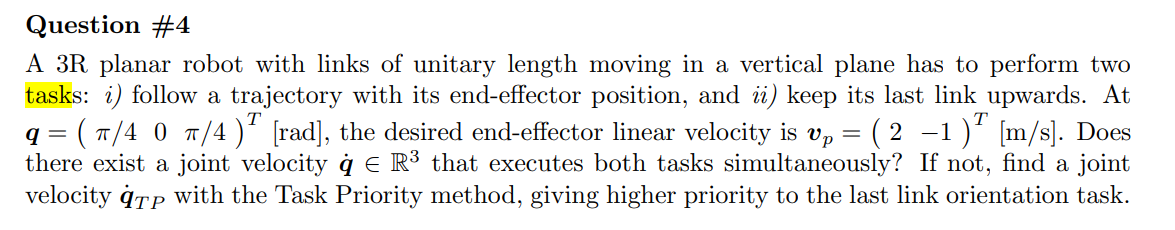

clc 
clear all
close all

% addpath("Functions/Robotics1") % Linux
% addpath("Functions/Robotics2") % Linux
addpath("Functions\Robotics1") % Windows
addpath("Functions\Robotics2") % Windows

syms q_1 q_2 q_3 q_dot_1 q_dot_2 q_dot_3 real

q = [q_1 q_2 q_3]';
q_dot = [q_dot_1 q_dot_2 q_dot_3]';

% unitary lenght so l = 1
f_2 = [cos(q_1) + cos(q_1 + q_2) + cos(q_1 + q_2 + q_3);
       sin(q_1) + sin(q_1 + q_2) + sin(q_1 + q_2 + q_3)];
f_1 = q_1 + q_2 + q_3;
f = [f_2; f_1]

$$f = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ q_{1}+q_{2}+q_{3} \end{array}\right)$$

J = jacobian(f, q)

$$J = \left(\begin{array}{ccc} -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)-\sin\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}+q_{3}\right)\\ \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}+q_{3}\right)\\ 1 & 1 & 1 \end{array}\right)$$

simplify(det(J))

$$ans = \sin\left(q_{2}\right)$$

J_q = subs(J, {q_1, q_2, q_3}, {pi/4, 0, pi/4})

$$J\_q = \left(\begin{array}{ccc} -\sqrt{2}-1 & -\frac{\sqrt{2}}{2}-1 & -1\\ \sqrt{2} & \frac{\sqrt{2}}{2} & 0\\ 1 & 1 & 1 \end{array}\right)$$

rank(J_q)

ans = 2

rank(J_q(1:2, :))

ans = 2

rank(J_q(3, :))

ans = 1

J_2 = J_q(1:2, :)

$$J\_2 = \left(\begin{array}{ccc} -\sqrt{2}-1 & -\frac{\sqrt{2}}{2}-1 & -1\\ \sqrt{2} & \frac{\sqrt{2}}{2} & 0 \end{array}\right)$$

J_1 = J_q(3, :)

$$J\_1 = \left(\begin{array}{ccc} 1 & 1 & 1 \end{array}\right)$$


% J_2 = jacobian(f_2, q)
% J_1 = jacobian(f_1, q)
% 
r_2_dot = [2 -1]';
r_1_dot = 0;
J_2_p = simplify(pinv(J_2));
J_1_p = simplify(pinv(J_1));
P_2 = simplify(eye(length(q)) - J_2_p*J_2)

$$P\_2 = \left(\begin{array}{ccc} \frac{1}{6} & -\frac{1}{3} & \frac{1}{6}\\ -\frac{1}{3} & \frac{2}{3} & -\frac{1}{3}\\ \frac{1}{6} & -\frac{1}{3} & \frac{1}{6} \end{array}\right)$$

P_1 = simplify(eye(length(q)) - J_1_p*J_1)

$$P\_1 = \left(\begin{array}{ccc} \frac{2}{3} & -\frac{1}{3} & -\frac{1}{3}\\ -\frac{1}{3} & \frac{2}{3} & -\frac{1}{3}\\ -\frac{1}{3} & -\frac{1}{3} & \frac{2}{3} \end{array}\right)$$

v1 = pinv(J_2*P_1)*(r_2_dot - J_2*J_1_p*r_1_dot)

$$v1 = \left(\begin{array}{c} -\frac{3\,\sqrt{2}}{4}\\ 0\\ \frac{3\,\sqrt{2}}{4} \end{array}\right)$$

%      + P_1*(eye(length(q)) - pinv(J_2*P_1)*(J_2*P_1))*r_2_dot
q_dot = vpa(J_1_p*r_1_dot + P_1*v1, 5)

$$q\_dot = \left(\begin{array}{c} -1.0607\\ 0\\ 1.0607 \end{array}\right)$$


r_dot_all = {r_1_dot, r_2_dot};
J_all = {J_1, J_2};
task_priority(J_all, r_dot_all)

$$ans = \left(\begin{array}{c} -1.0607\\ 0\\ 1.0607 \end{array}\right)$$